# **IO206 - Digital Input**

This example shows you how to use the IO206 to input digital signals and which settings you must first define.

The IO206 I/O module is a digital input module with Simulink® driver blocks.The 32 digital inputs offer a 8 V, 12 V or 24 V input range. The following variants are available: the IO206 with 24 V inputs, the IO206-12V with 12 V inputs, and the IO206-8V with 8 V inputs. You  can also adjust the debounce time of the digital inputs within the specific time parameters available.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO206 I/O module installed

- Connector cable from the I/O module to the terminal board

- 50-pin terminal board with jumper wires

- External signal generator (Depending on I/O module, 8V/12V/24V)

### Pin Mapping/Connection Diagram/Test Setup

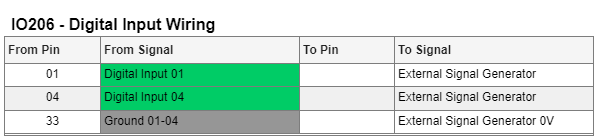

On the terminal board of the digital I/O module, connect pin 01 and pin 04 with the external signal generator and pin 33 with the ground or 0V of the signal generator.

[IO206 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io206_pin_mapping)

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO206_DigitalInput';
open_system(modelName);

### Model Description

The Simulink model features one [IO206 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io206_setup) block, one [IO206 Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io206_read) block and one [Gain](https://ch.mathworks.com/help/simulink/slref/gain.html) block.

The [IO206 Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io206_read) block read the signals from the external signal generator and outputs a 0 or 1 depending on the threshold. Please note that the [Gain](https://ch.mathworks.com/help/simulink/slref/gain.html) block just enables a better visualization of the two signals.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode
% set_param(modelName,'SimulationCommand','start')      % start real-time application through Simulink toolstrip

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;


### Check the Results

The blue signal is channel one and the green signal is channel 4 of the [IO206 Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io206_read) block.

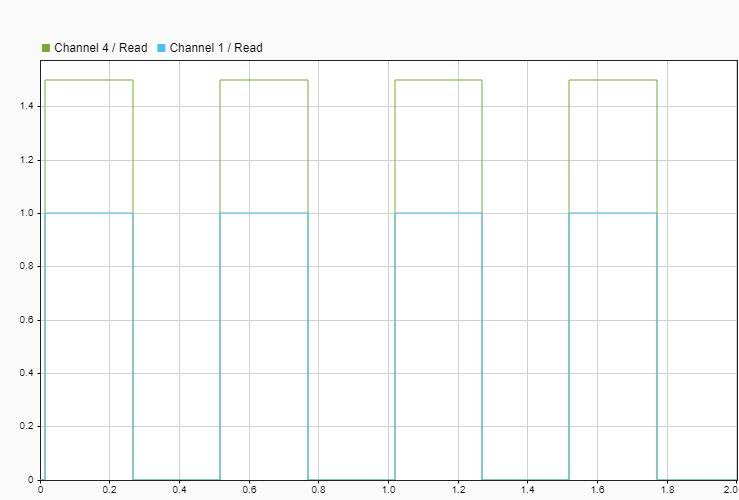

## Additional References

- [IO206 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io206)